mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122


X0 = [0.803317447531649	0 0 0.333418772378925]

X0 =     0.8033         0         0    0.3334


C1 = jacobiConstant([0.803317447531649	0],[0 0.333418772378925],mu)

C1 = 3.0946

STM = reshape(eye(4),16,[])';
Xunstable = [X0 STM]';
epsilon=1e-4;
periodoUnstable = 3.20588680682668;
X_mainfold_stable_positive = calculateStableMainfold(periodoUnstable,Xunstable,mu,k,epsilon,1,false);


X_mainfold_stable_negative = calculateStableMainfold(periodoUnstable,Xunstable,mu,k,epsilon,-1,false);

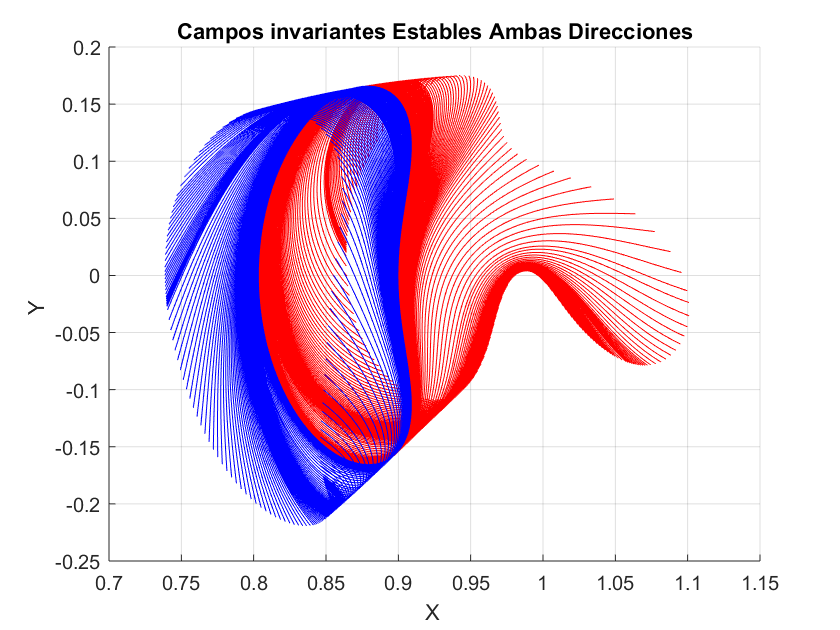


plotStableMainfold(X_mainfold_stable_positive,periodoUnstable,k,mu,'r')
plotStableMainfold(X_mainfold_stable_negative,periodoUnstable,k,mu,'b')
title('Campos invariantes Estables Ambas Direcciones');
xlabel('X ');
ylabel('Y ');
grid on;